# Detect Image Anomalies Using Explainable FCDD Network

This example shows how to detect defects on pill images using a one-class fully convolutional data description (FCDD) anomaly detection network.

A crucial goal of anomaly detection is for a human observer to be able to understand why a trained network classifies images as anomalies. FCDD enables e*xplainable classification*, which supplements the class prediction with information that justifies how the neural network reached its classification decision [1]. The FCDD network returns a heatmap with the probability that each pixel is anomalous. The classifier labels images as normal or anomalous based on the mean value of the anomaly score heatmap.

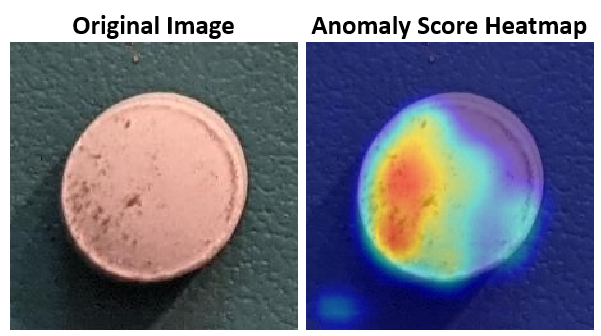

## Download Pill Images for Classification Data Set

This example uses the PillQC data set. The data set contains images from three classes: `normal` images without defects, `chip` images with chip defects in the pills, and `dirt` images with dirt contamination. The data set provides 149 `normal` images, 43 `chip` images, and 138 `dirt` images. The size of the data set is 3.57 MB.

Set `dataDir` as the desired location of the data set. Download the data set using the `downloadPillQCData` helper function. This function is attached to the example as a supporting file. The function downloads a ZIP file and extracts the data into the subdirectories `chip`, `dirt`, and `normal`.

dataDir = fullfile(tempdir,"PillDefects");
downloadPillQCData(dataDir)

This image shows an example image from each class. A normal pill with no defects is on the left, a pill contaminated with dirt is in the middle, and a pill with a chip defect is on the right. While the images in this data set contain instances of shadows, focus blurring, and background color variation, the approach used in this example is robust to these image acquisition artifacts. 

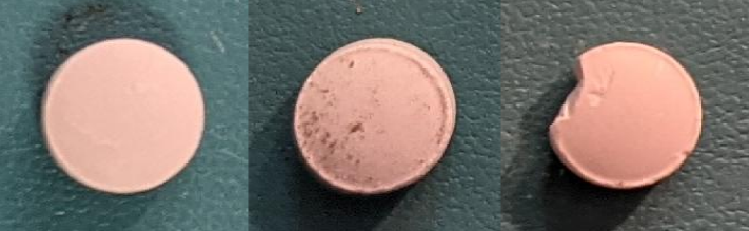

## Load and Preprocess Data

Create an `imageDatastore` that reads and manages the image data. Label each image as `chip`, `dirt`, or `normal` according to the name of its directory.

imageDir = fullfile(dataDir,"pillQC-main","images");
imds = imageDatastore(imageDir,IncludeSubfolders=true,LabelSource="foldernames");

### Partition Data into Training, Calibration, and Test Sets

Create training, calibration, and test sets using the [`splitAnomalyData`](docid:vision_ref#mw_00a45622-0c54-4b9f-9c32-ce15a3be6f47) function. This example implements an FCDD approach that uses outlier exposure, in which the training data consists primarily of normal images with the addition of a small number of anomalous images. Despite training primarily on samples only of normal scenes, the model learns how to distinguish between normal and anomalous scenes.

Allocate 50% of the normal images and a small percentage (5%) of each anomaly class in the training data set. Allocate 10% of the normal images and 20% of each anomaly class to the calibration set. Allocate the remaining images to the test set.

normalTrainRatio  = 0.5;
anomalyTrainRatio = 0.0;
normalCalRatio  = 0.10;
anomalyCalRatio = 0.20;
normalTestRatio  = 1 - (normalTrainRatio + normalCalRatio);
anomalyTestRatio = 1 - (anomalyTrainRatio + anomalyCalRatio);

anomalyClasses = ["chip","dirt"];
[imdsTrain,imdsCal,imdsTest] = splitAnomalyData(imds,anomalyClasses, ...
    NormalLabelsRatio=[normalTrainRatio normalCalRatio normalTestRatio], ...
    AnomalyLabelsRatio=[anomalyTrainRatio anomalyCalRatio anomalyTestRatio]);

Splitting anomaly dataset
-------------------------
* Finalizing... Done.
* Number of files and proportions per class in all the datasets:

                     Input                 Train              Validation                Test        
              NumFiles     Ratio     NumFiles    Ratio    NumFiles     Ratio     NumFiles     Ratio 
              ___________________    _________________    ___________________    ___________________
    chip         43        0.1303        0         0          9       0.17647       34       0.16667
    dirt        138       0.41818        0         0         28       0.54902      110       0.53922
    normal      149       0.45152       75         1         14       0.27451       60       0.29412


Further split the training data into two datastores, one containing only normal data and another containing only anomaly data.

imdsNormalTrain = imdsTrain;

### Augment Training Data

Augment the training data by using the [`transform`](docid:matlab_ref#mw_16489124-fe7e-4381-b715-8d3b8b30a9f6) function with custom preprocessing operations specified by the helper function `augmentDataForPillAnomalyDetector`. The helper function is attached to the example as supporting files.

The `augmentDataForPillAnomalyDetector` function randomly applies 90 degree rotation and horizontal and vertical reflection to each input image. 

imdsNormalTrain = transform(imdsNormalTrain,@augmentDataForPillAnomalyDetector);
% imdsAnomalyTrain = transform(imdsAnomalyTrain,@augmentDataForPillAnomalyDetector);

Add binary labels to the calibration and test data sets by using the `transform` function with the operations specified by the `addLabelData` helper function. The helper function is defined at the end of this example, and assigns images in the `normal` class a binary label `0` and images in the `chip` or `dirt` classes a binary label `1`.

dsCal = transform(imdsCal,@addLabelData,IncludeInfo=true);
dsTest = transform(imdsTest,@addLabelData,IncludeInfo=true);

Visualize a sample of nine augmented training images.

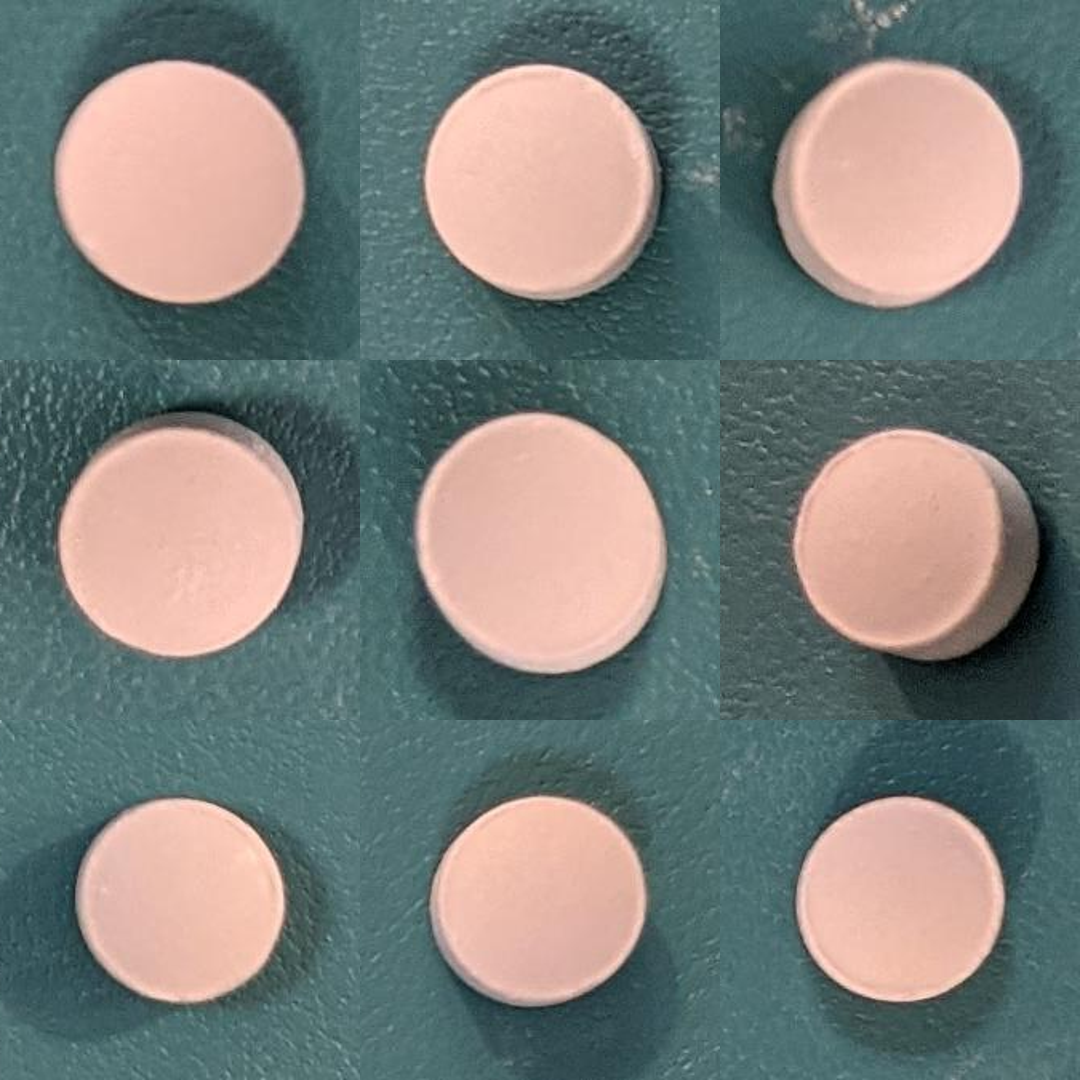

exampleData = readall(subset(imdsNormalTrain,1:9));
montage(exampleData(:,1));

## Create FCDD Model

This example uses a fully convolutional data description (FCDD) model [1]. The basic idea of FCDD is to train a network to produce an anomaly score map that describes the probability that each region in the input image contains anomaly content.

The [`pretrainedEncoderNetwork`](docid:images_ref#mw_36751d4c-f29e-47f0-8983-72ac90bb0c20) function returns the first three downsampling stages of an ImageNet pretrained Inception-v3 network for use as a pretrained backbone.

% backbone = pretrainedEncoderNetwork("inceptionv3",3);

Create an FCDD anomaly detector network by using the [`fcddAnomalyDetector`](docid:vision_ref#mw_939ffbbe-6e8e-4cf5-8127-afd026612001) function with the Inception-v3 backbone.

net = patchCoreAnomalyDetector(backbone='resnet18')

net =   patchCoreAnomalyDetector のプロパティ:

    Threshold: []
    ImageSize: []

## Train Network or Download Pretrained Network

By default, this example downloads a pretrained version of the FCDD anomaly detector using the helper function `downloadTrainedNetwork`. The helper function is attached to this example as a supporting file. You can use the pretrained network to run the entire example without waiting for training to complete.

To train the network, set the `doTraining` variable in the following code to `true`. Specify the number of epochs to use for training `numEpochs` by entering a value in the field. Train the model by using the [`trainFCDDAnomalyDetector`](docid:vision_ref#mw_9a47c35e-f141-48b7-b938-23f6915a1cb3) function.

Train on one or more GPUs, if available. Using a GPU requires Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU. For more information, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Training takes about 3 minutes on an NVIDIA Titan RTX™.

doTraining = true;
numEpochs = 200;
if doTraining
    options = trainingOptions("adam", ...
        Shuffle="every-epoch",...
        MaxEpochs=numEpochs,InitialLearnRate=1e-4, ...
        MiniBatchSize=32,...
        BatchNormalizationStatistics="moving");
    detector = trainPatchCoreAnomalyDetector(imdsNormalTrain,net);
    modelDateTime = string(datetime("now",Format="yyyy-MM-dd-HH-mm-ss"));
    save(fullfile(dataDir,"trainedPillAnomalyDetector-"+modelDateTime+".mat"),"detector");
else
    trainedPillAnomalyDetectorNet_url = "https://ssd.mathworks.com/supportfiles/"+ ...
        "vision/data/trainedFCDDPillAnomalyDetectorSpkg.zip";
    downloadTrainedNetwork(trainedPillAnomalyDetectorNet_url,dataDir);
    load(fullfile(dataDir,"folderForSupportFilesInceptionModel", ...
        "trainedPillFCDDNet.mat"));
end

Computing Input Normalization Statistics.
Training PatchCore Model.
-------------------------

Step 1: Computing embeddings for each minibatch
.Done creating uncompressed train embeddings.
Step 2: Compress train embeddings at 0.1 factor to create a coreset...

Computing coreset samples
....
Completed 3155 of 6307  時間: 計算中...
....Done compressing train embeddings (coreset).
Done training PatchCore model.


## Set Anomaly Threshold

Select an anomaly score threshold for the anomaly detector, which classifies images based on whether their scores are above or below the threshold value. This example uses a calibration data set that contains both normal and anomalous images to select the threshold.

Obtain the mean anomaly score and ground truth label for each image in the calibration set.

scores = predict(detector,dsCal);
labels = imdsCal.Labels ~= "normal";

Plot a histogram of the mean anomaly scores for the normal and anomaly classes. The distributions are well separated by the model-predicted anomaly score.

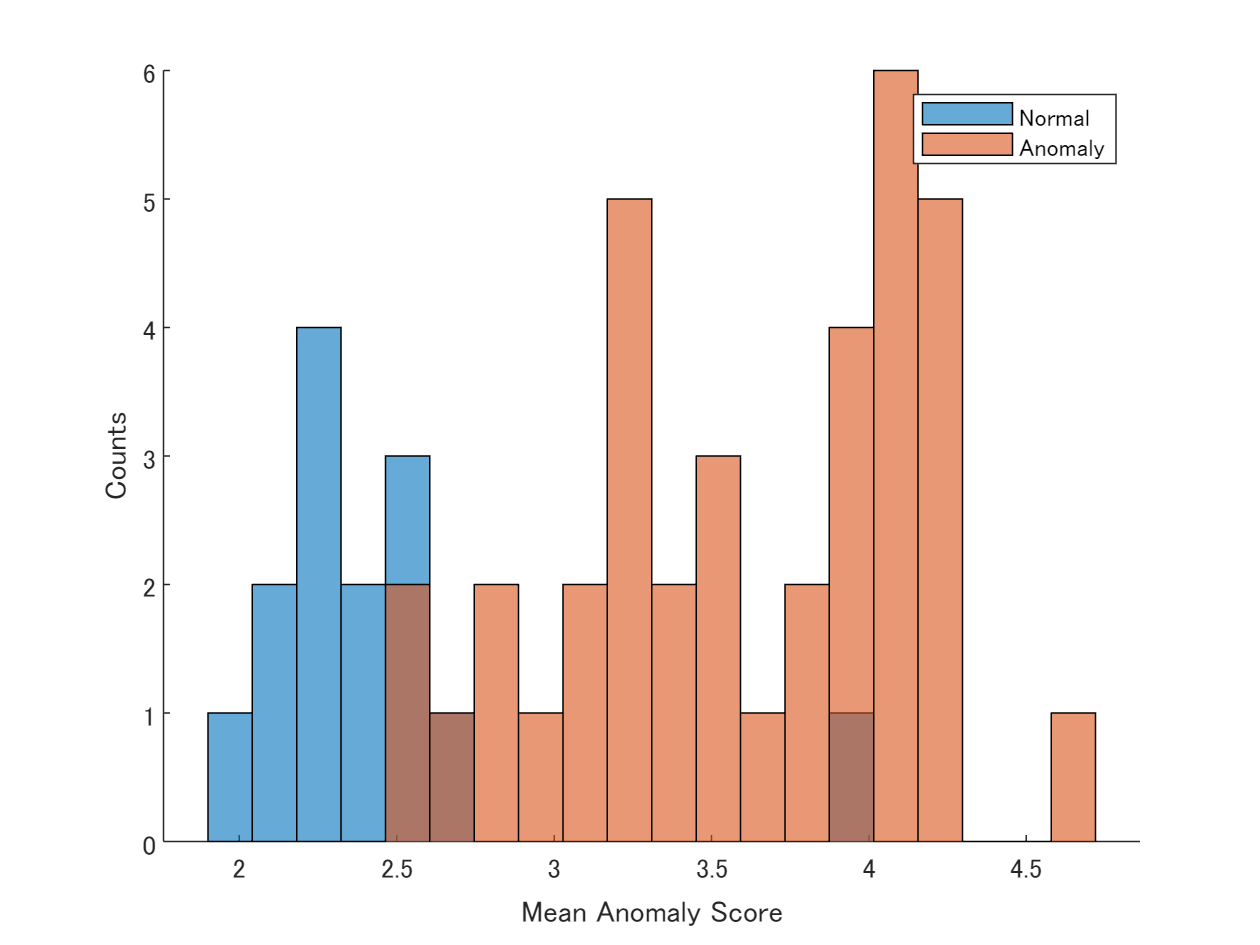

numBins = 20;
[~,edges] = histcounts(scores,numBins);
figure
hold on
hNormal = histogram(scores(labels==0),edges);
hAnomaly = histogram(scores(labels==1),edges);
hold off
legend([hNormal,hAnomaly],"Normal","Anomaly")
xlabel("Mean Anomaly Score")
ylabel("Counts")

Calculate the optimal anomaly threshold by using the [`anomalyThreshold`](docid:vision_ref#mw_dc5fa7ef-5996-43b5-b362-a09f68ba377a) function. Specify the first two input arguments as the ground truth labels, `labels`, and predicted anomaly scores, `scores`, for the calibration data set. Specify the third input argument as `true` because true positive anomaly images have a `labels` value of `true`. The `anomalyThreshold` function returns the optimal threshold and the receiver operating characteristic (ROC) curve for the detector, stored as an [`rocmetrics`](docid:nnet_ref#mw_d9f7dc7d-4019-47b7-a295-342aeb2e9fc5) object.

[thresh,roc] = anomalyThreshold(labels,scores,true);

Set the `Threshold` property of the anomaly detector to the optimal value.

detector.Threshold = thresh;

Plot the ROC by using the [`plot`](docid:nnet_ref#mw_e042d97f-0836-4b22-a353-bcb8598c4986) object function of `rocmetrics`. The ROC curve illustrates the performance of the classifier for a range of possible threshold values. Each point on the ROC curve represents the false positive rate (*x*-coordinate) and true positive rate (*y*-coordinate) when the calibration set images are classified using a different threshold value. The solid blue line represents the ROC curve. The red dashed line represents a no-skill classifier corresponding to a 50% success rate. The ROC area under the curve (AUC) metric indicates classifier performance, and the maximum ROC AUC corresponding to a perfect classifier is 1.0.

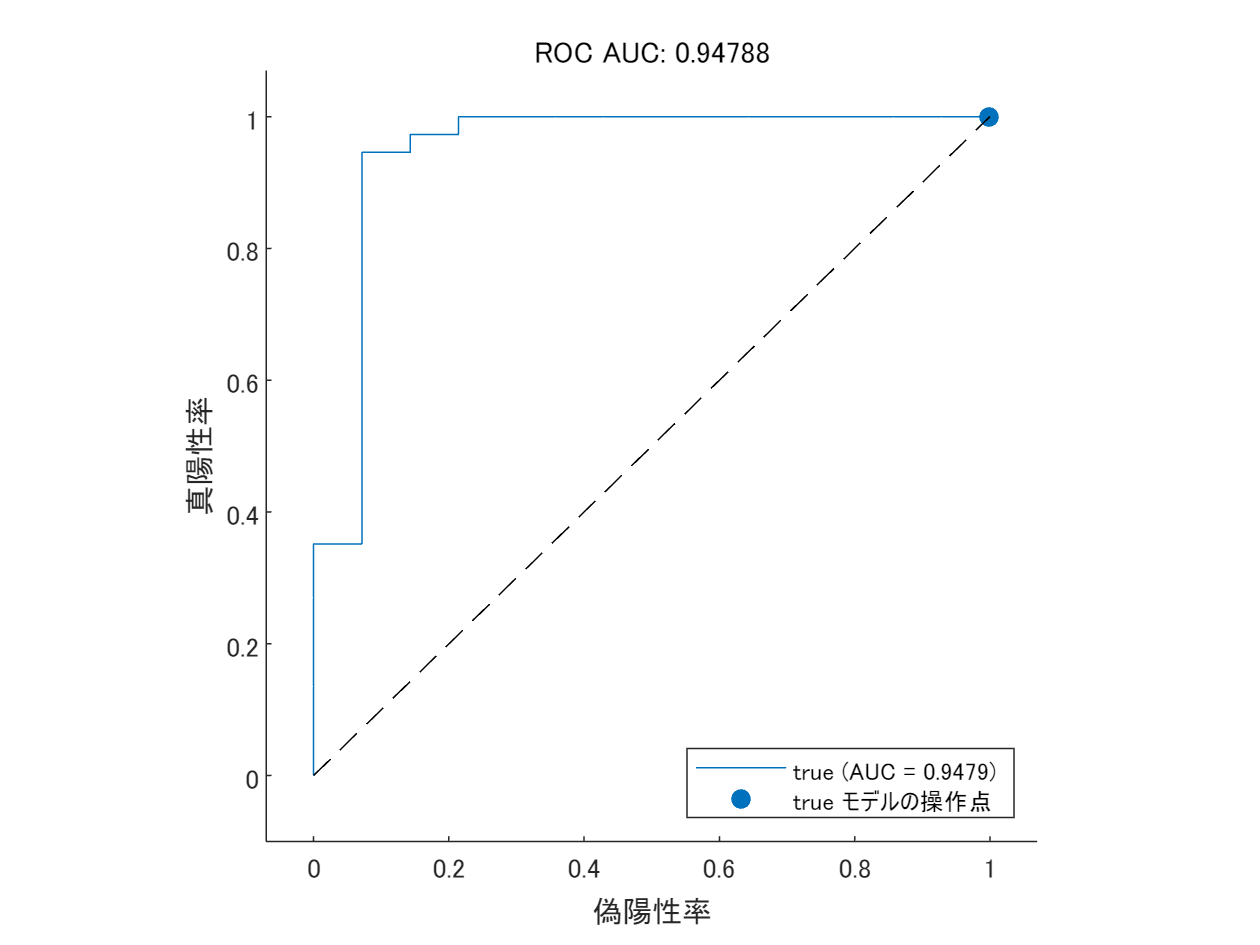

plot(roc)
title("ROC AUC: "+ roc.AUC)

## Evaluate Classification Model

Classify each image in the test set as either normal or anomalous.

testSetOutputLabels = classify(detector,dsTest);

Get the ground truth labels of each test image.

testSetTargetLabels = dsTest.UnderlyingDatastores{1}.Labels;

Evaluate the anomaly detector by calculating performance metrics by using the [`evaluateAnomalyDetection`](docid:vision_ref#mw_5f0f95db-ed38-4731-a5d5-5930890ed27f) function. The function calculates several metrics that evaluate the accuracy, precision, sensitivity, and specificity of the detector for the test data set.

metrics = evaluateAnomalyDetection(testSetOutputLabels,testSetTargetLabels,anomalyClasses);

Evaluating anomaly detection results
------------------------------------
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    Precision    Recall     Specificity    F1Score    FalsePositiveRate    FalseNegativeRate
    ______________    ____________    _________    _______    ___________    _______    _________________    _________________
       0.95098          0.93125        0.9527      0.97917      0.88333      0.96575         0.11667             0.020833     


The `ConfusionMatrix` property of `metrics` contains the confusion matrix for the test set. Extract the confusion matrix and display a confusion plot. The classification model in this example is very accurate and predicts a small percentage of false positives and false negatives.

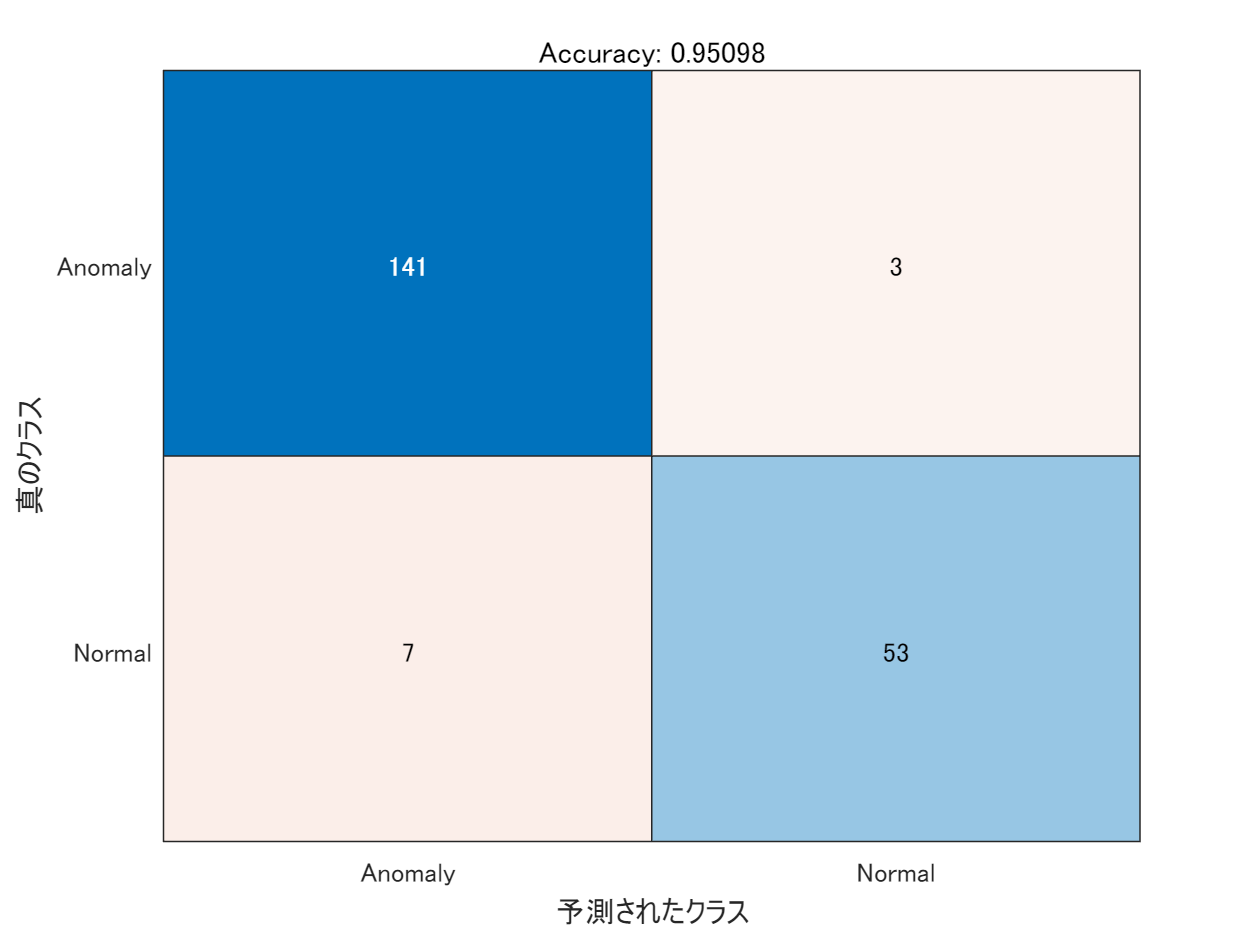

M = metrics.ConfusionMatrix{:,:};
confusionchart(M,["Normal","Anomaly"])
acc = sum(diag(M)) / sum(M,"all");
title("Accuracy: "+acc)

If you specify multiple anomaly class labels, such as `dirt` and `chip` in this example, the `evaluateAnomalyDetection` function calculates metrics for the whole data set and for each anomaly class. The per-class metrics are returned in the `ClassMetrics` property of the [`anomalyDetectionMetrics`](docid:vision_ref#mw_d84ca23c-c6df-4124-88ae-a8bc304fa209) object, `metrics`.

metrics.ClassMetrics

ans = 2×2 table
               Accuracy    AccuracyPerSubClass
               ________    ___________________
    Normal     0.88333         {1×1 table}    
    Anomaly    0.97917         {2×1 table}    

metrics.ClassMetrics(2,"AccuracyPerSubClass").AccuracyPerSubClass{1}

ans = 2×1 table
            AccuracyPerSubClass
            ___________________
    chip                1      
    dirt          0.97273      

## Explain Classification Decisions

You can use the anomaly heatmap predicted by the anomaly detector to help explain why an image is classified as normal or anomalous. This approach is useful for identifying patterns in false negatives and false positives. You can use these patterns to identify strategies for increasing class balancing of the training data or improving the network performance.

### Calculate Anomaly Heat Map Display Range

Calculate a display range that reflects the range of anomaly scores observed across the entire calibration set, including normal and anomalous images. Using the same display range across images allows you to compare images more easily than if you scale each image to its own minimum and maximum.  Apply the display range for all heatmaps in this example.

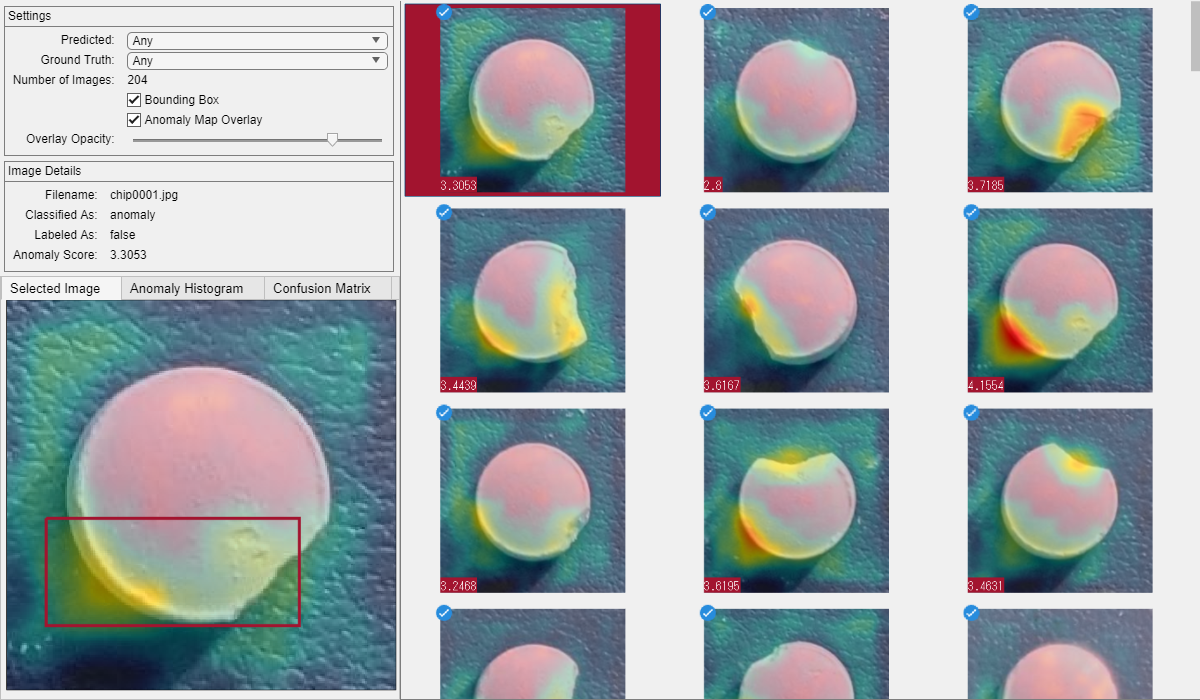

% 以下はUIツールを利用するために付加
anomalyScores_test =  predict(detector,dsTest);
viewAnomalyDetectionResults(detector,dsTest,imdsTest.Labels=='normal',anomalyScores_test,false);

% 以降のスクリプトはUIツールで再現可能だが元のサンプルとの差分がわかりやすいため残した。


minMapVal = inf;
maxMapVal = -inf;
reset(dsCal)
while hasdata(dsCal)
    img = read(dsCal);
    map = anomalyMap(detector,img{1});
    minMapVal = min(min(map,[],"all"),minMapVal);
    maxMapVal = max(max(map,[],"all"),maxMapVal);
end
displayRange = [minMapVal,maxMapVal];

### View Heatmap of Anomaly Image

Select an image of a correctly classified anomaly. This result is a true positive classification. Display the image.

testSetAnomalyLabels = testSetTargetLabels ~= "normal";
idxTruePositive = find(testSetAnomalyLabels' & testSetOutputLabels,1,"last");
dsExample = subset(dsTest,idxTruePositive);
img = read(dsExample);
img = img{1};
map = anomalyMap(detector,img);
imshow(anomalyMapOverlay(img,map,MapRange=displayRange,Blend="equal"))

### View Heatmap of Normal Image

Select and display an image of a correctly classified normal image. This result is a true negative classification.

idxTrueNegative = find(~(testSetAnomalyLabels' | testSetOutputLabels));
dsExample = subset(dsTest,idxTrueNegative);
img = read(dsExample);
img = img{1};
map = anomalyMap(detector,img);
imshow(anomalyMapOverlay(img,map,MapRange=displayRange,Blend="equal"))

### View Heatmaps of False Negative Images

False negatives are images with pill defect anomalies that the network classifies as normal. Use the explanation from the network to gain insights into the misclassifications.

Find any false negative images from the test set. Obtain heatmap overlays of the false negative images by using the `transform` function. The operations of the transform are specified by an anonymous function that applies the [`anomalyMapOverlay`](docid:vision_ref#mw_ee16788a-f600-493c-bdf1-603e63f24b0e) function to obtain heatmap overlays for each false negative in the test set.

falseNegativeIdx = find(testSetAnomalyLabels' & ~testSetOutputLabels);
if ~isempty(falseNegativeIdx)
    fnExamples = subset(dsTest,falseNegativeIdx);
    fnExamplesWithHeatmapOverlays = transform(fnExamples,@(x) {...
        anomalyMapOverlay(x{1},anomalyMap(detector,x{1}), ...
        MapRange=displayRange,Blend="equal")});
    fnExamples = readall(fnExamples);
    fnExamples = fnExamples(:,1);
    fnExamplesWithHeatmapOverlays = readall(fnExamplesWithHeatmapOverlays);
    montage(fnExamples)
    montage(fnExamplesWithHeatmapOverlays)
else
    disp("No false negatives detected.")
end

### View Heatmaps of False Positive Images

False positives are images without pill defect anomalies that the network classifies as anomalous. Find any false positives in the test set. Use the explanation from the network to gain insights into the misclassifications. For example, if anomalous scores are localized to the image background, you can explore suppressing the background during preprocessing.

falsePositiveIdx = find(~testSetAnomalyLabels' & testSetOutputLabels);
if ~isempty(falsePositiveIdx)
    fpExamples = subset(dsTest,falsePositiveIdx);
    fpExamplesWithHeatmapOverlays = transform(fpExamples,@(x) { ...
        anomalyMapOverlay(x{1},anomalyMap(detector,x{1}), ...
        MapRange=displayRange,Blend="equal")});
    fpExamples = readall(fpExamples);
    fpExamples = fpExamples(:,1);
    fpExamplesWithHeatmapOverlays = readall(fpExamplesWithHeatmapOverlays);
    montage(fpExamples)
    montage(fpExamplesWithHeatmapOverlays)
else
    disp("No false positives detected.")
end

## Supporting Functions

The `addLabelData` helper function creates a one-hot encoded representation of label information in `data`.

function [data,info] = addLabelData(data,info)
    if info.Label == categorical("normal")
        onehotencoding = 0;
    else
        onehotencoding = 1;
    end
    data = {data,onehotencoding};
end

## References

[1] Liznerski, Philipp, Lukas Ruff, Robert A. Vandermeulen, Billy Joe Franks, Marius Kloft, and Klaus-Robert Müller. "Explainable Deep One-Class Classification." Preprint, submitted March 18, 2021. [https://arxiv.org/abs/2007.01760](https://arxiv.org/abs/2007.01760).

[2] Ruff, Lukas, Robert A. Vandermeulen, Billy Joe Franks, Klaus-Robert Müller, and Marius Kloft. "Rethinking Assumptions in Deep Anomaly Detection." Preprint, submitted May 30, 2020. [https://arxiv.org/abs/2006.00339](https://arxiv.org/abs/2006.00339).

[3] Simonyan, Karen, and Andrew Zisserman. "Very Deep Convolutional Networks for Large-Scale Image Recognition." Preprint, submitted April 10, 2015. [https://arxiv.org/abs/1409.1556](https://arxiv.org/abs/1409.1556).

[4] *ImageNet*. [https://www.image-net.org](https://www.image-net.org).

*Copyright 2022 The MathWorks, Inc.*